## Viscous Fluid Image Registration

- Loading images

Template = dicomread("Template.dcm");
Source = dicomread("Source.dcm");

Initialize various conditions and parameters

Re = 1; % Reynolds Number
% Reynolds Number is in this case due in part to the fact
% that the aim is to wholely incorporate the diffusive
% mechaninism into the model without performing alterations
x0=0;
y0=0;

dt = 10; % initialy define the maximal time step
Umax =  1e-1; % define the deformation Limit - Need To come Back
% to this
tInitial = 0;  % define the initial time step
tFinal = 20; % define maximal iterations;

Initialize the discretize mesh/grid on which we will numerically solve the viscous fluid pde

% grid/mesh size shoud match that of the template 
[rows, cols] = size(Template);
gridLengthX = rows; % grid width
gridlenghtY = cols; % grid height
% define number of control points in each direction
numPointsX = rows * 2;
numPointsY = cols * 2;
% define number of time step until we observe current system
% state visualy
numSteps = 20;

Produce Mesh/Grid and other time step parameters

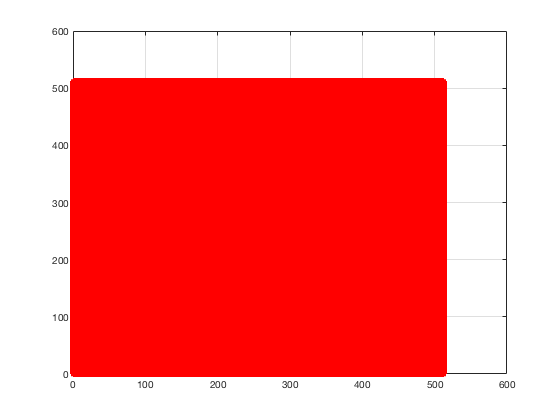

numTimeSteps = ceil(tFinal/dt);
dt = tFinal/numTimeSteps;

% Note that we must include a few points past the border in order
% in order to efficiently perform linear interpolation at image boundaries
x = linspace(0, gridLengthX, numPointsX+1);
y = linspace(0, gridlenghtY, numPointsY+1);

% compute the spacing between each control point in x and y direction
dtX = gridLengthX/numPointsX;
dtY = gridlenghtY/numPointsY;

% create a meshgrid
[X, Y] = meshgrid(x,y);
%[x,y]=meshgrid(x0:dx:LX,y0:dy:LY);
plot(X,Y,'*r');hold on;grid on

%[xx,yy]=meshgrid(0.1:0.1:1.1,0.1:0.1:1.1);

Define Initial conditions

% initialize displacement field
Ux = zeros(gridLengthX-1, gridlenghtY);
Uy = zeros(gridLengthX, gridlenghtY-1);

% initialize velocity field
Vx = zeros(gridLengthX-1, gridlenghtY);
Vy = zeros(gridLengthX, gridlenghtY-1);